load test_data.mat -mat

data = noise_remove_LPF(data);
range = 0:1:length(data(:,1))-1;
temp = abs(data);
count = 0;
idx = 1;
%plot(range,temp(:,1))


while count < 10 && count < length(data(:,1))
    if temp(idx,1) > .08
        count = count + 1;
    else
        count = 0;
    end
    idx = idx + 1;
end
idx = idx - 1;
begin = idx;
count = 0;
while count < 30 && count < length(data(:,1))
    if temp(idx,1) < .04
        count = count + 1;
    else
        count = 0;
    end
    idx = idx + 1;
end
idx = idx - 1;

%count = 0;
%fin = idx;
%while count < 10 && count < length(data(:,1))
%    if temp(fin,1) > .03
%        count = count + 1;
%    else
%        count = 0;
%    end
%    fin = fin + 1;
%end
%fin = fin - 1;
%count = 0;
%while count < 30 && count < length(data(:,1))
%    if temp(fin,1) < .02
%        count = count + 1;
%    else
%        count = 0;
%    end
%    fin = fin + 1;
%end
%fin = fin - 1;

f1 = figure;
figure(f1);

data(1:1:idx,:) = data(1:1);
%data(fin:1:end,:) = data(1:1);
data(1:1:end-begin,:) = data(begin+1:1:end,:);
data(1+end-begin:1:end,:) = data(1:1);

his = max(temp(idx:1:end,:))

his =    0.340505841945199   0.290755646707267   0.418881484722835   0.831118675124963


rels = his/max(his)

rels =    0.409695813770521   0.349836497974914   0.503997199509269   1.000000000000000


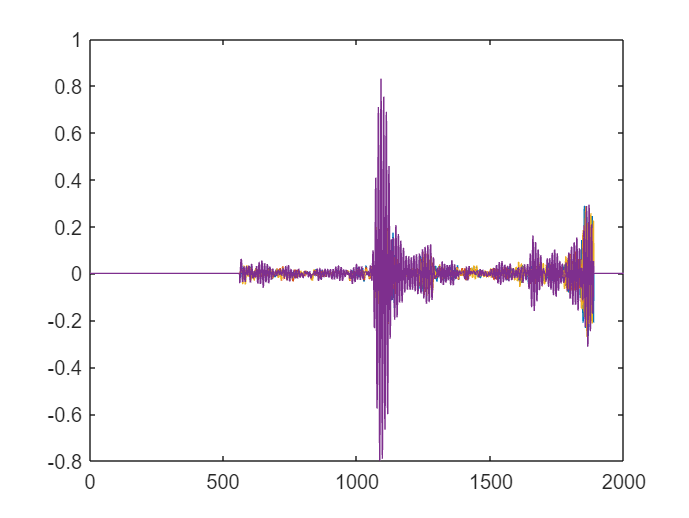


plot(range,data(:,1))
hold on
plot(range,data(:,2))
plot(range,data(:,3))
plot(range,data(:,4))

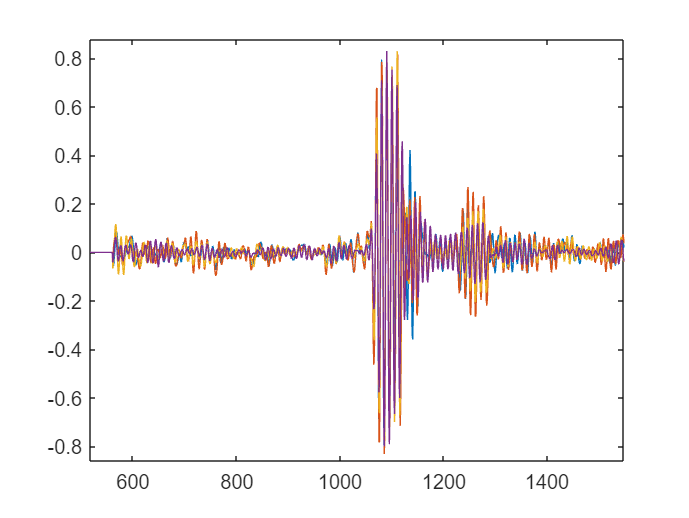


for n = 1:1:4
    data(:,n) = data(:,n)/rels(n);
end

f2 = figure;
figure(f2);

plot(range,data(:,1))
hold on
plot(range,data(:,2))
plot(range,data(:,3))
plot(range,data(:,4))

xlim([517 1548])
ylim([-0.86 0.88])